clc
clear

Newton-Raphson 


$$x_{i+1} =x_i -\frac{f\left(x_i \right)}{f`\left(x_i \right)}$$


Only needs 1 point

Have to be able to calculate Derivative

Failure points:

    Inflection point

    Local Extrema

Secant Method

Slope Approx $f`\left(x_i \right)\approx \frac{f\left(x_{i-1} \right)-f\left(x_i \right)}{x_{i-1} -x_i }$


$$x_{i+1} =x_i -f\left(x_i \right)\left\lbrack \frac{x_{i-1} -x_i }{f\left(x_{i-1} \right)-f\left(x_i \right)}\right\rbrack$$


No Derivative Required

2 points

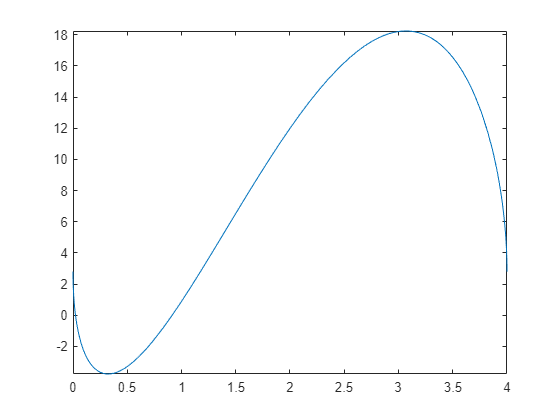

r = 2;
L = 5;
V = 8;

f = @(h) L*((r^2)*cos((r - h)/r)-(r-h).*sqrt(2*r*h-h.^2))-V;
fplot(f, [0, 4])


x_1 = 0.5-f(.5)*((.25-.5)/(f(.25)-f(.5)))

x_1 = 2.7555

Inverse Quadratic Interpolation

fast, complex

Fzero

built into matlab

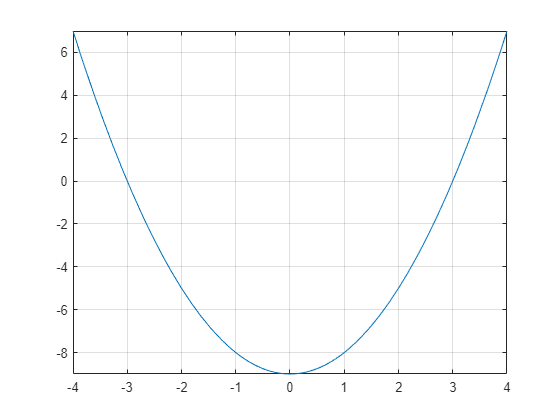

f = @(x) x.^2-9;
fplot(f, [-4,4])
grid on

x = fzero(f,4)

x = 3

x = fzero(f, [-4,1])

x = -3

x = fzero(f,0)

x = -3